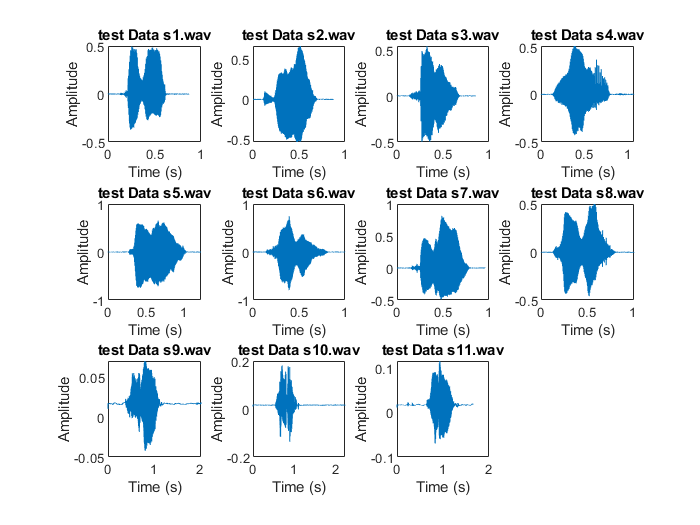

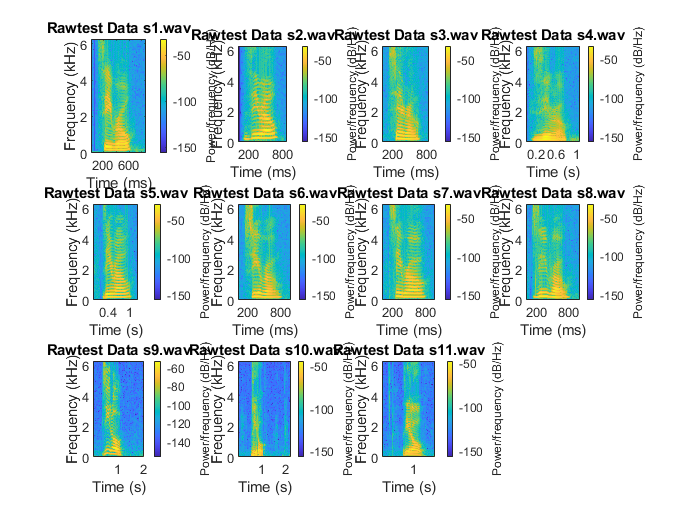

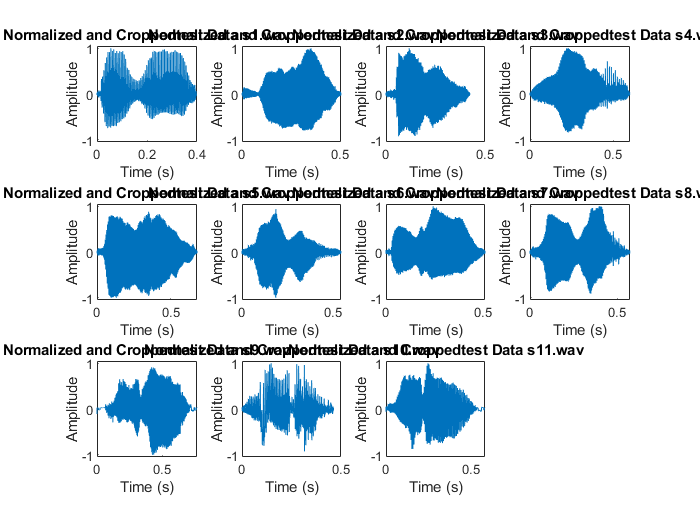

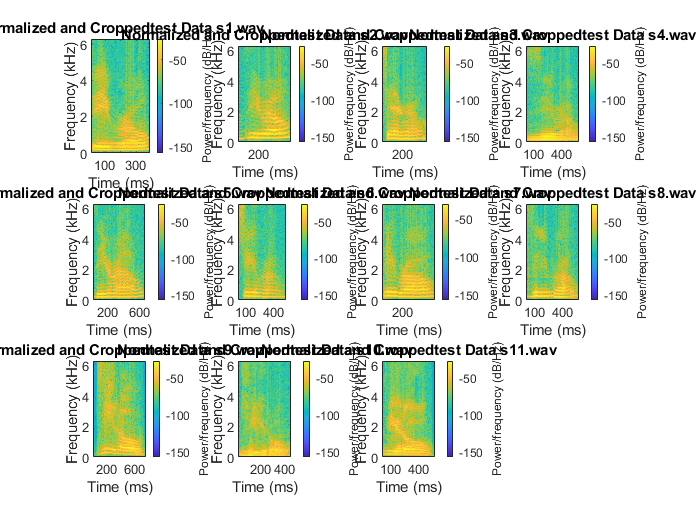

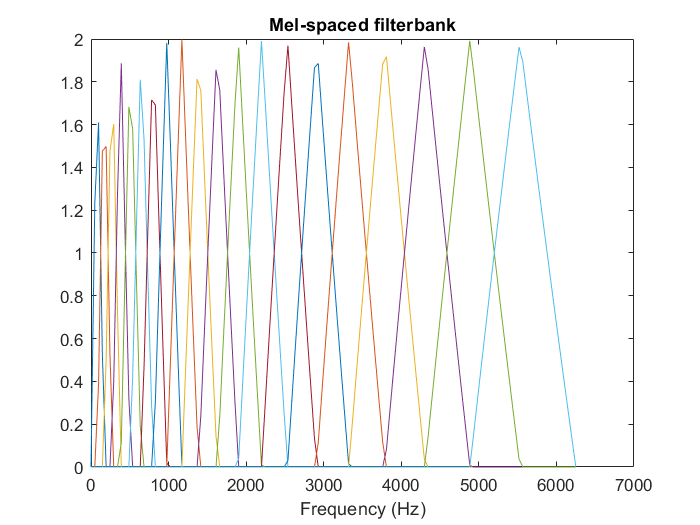

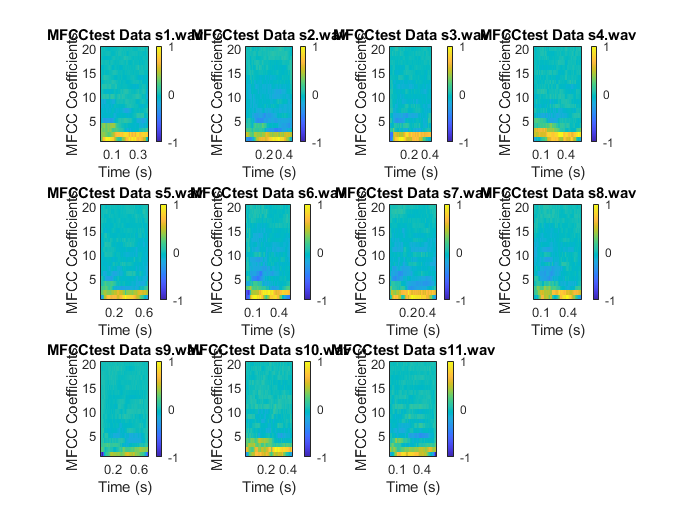

clear   
% Train
% [cepstrum, t_out] = mfcc('train', 256, 20)
% %% Determine Centroid
% K=4; % number of clusters
% N = 20; %number of MFCC features to use;
% distortion_eps = 0.05;
% for i=1:size(cepstrum,2)
%     [codebook{i}, clusterID{i}, D{i}] = LBG((cepstrum{i}(1:N,:))', K, distortion_eps);
% end
% save codebook.mat codebook
% Test
[cepstrum,t] = mfcc('test',256,20);

%
K=4; % number of clusters
N = 20; %number of MFCC features to use;
distortion_eps = 0.05;
for i=1:size(cepstrum,2)
    [codebook_test{i}, clusterID{i}, D{i}] = LBG((cepstrum{i}(1:N,:))', K, distortion_eps);
end

total_samples = length(codebook_test);
correct_guess = 0;
for i=1:total_samples
    speaker_estimate = classify(codebook_test{i})
    if (i == speaker_estimate)
        correct_guess = correct_guess + 1;
    end
end

speaker_estimate = 1

speaker_estimate = 2

speaker_estimate = 3

speaker_estimate = 4

speaker_estimate = 5

speaker_estimate = 6

speaker_estimate = 7

speaker_estimate = 8

speaker_estimate = 9

speaker_estimate = 10

speaker_estimate = 11


disp(correct_guess/total_samples*100)

   100

